clear;clc;close all;
% Gerando as variáveis - sem feedforward
tempo1 = 0;
degrau1 = 0;
resposta1 = 0;
tempo2 = 0;
degrau2 = 0;
resposta2 = 0;
tempo3 = 0;
degrau3 = 0;
resposta3 = 0;
tempo4 = 0;
degrau4 = 0;
resposta4 = 0;
tempo5 = 0;
degrau5 = 0;
resposta5 = 0;
tempo6 = 0;
degrau6 = 0;
resposta6 = 0;

% Gerando variáveis com o feedforward

tempoff1 = 0;
degrauff1 = 0;
respostaff1 = 0;
tempoff2 = 0;
degrauff2 = 0;
respostaff2 = 0;
tempoff3 = 0;
degrauff3 = 0;
respostaff3 = 0;
tempoff4 = 0;
degrauff4 = 0;
respostaff4 = 0;
tempoff5 = 0;
degrauff5 = 0;
respostaff5 = 0;
tempoff6 = 0;
degrauff6 = 0;
respostaff6 = 0;

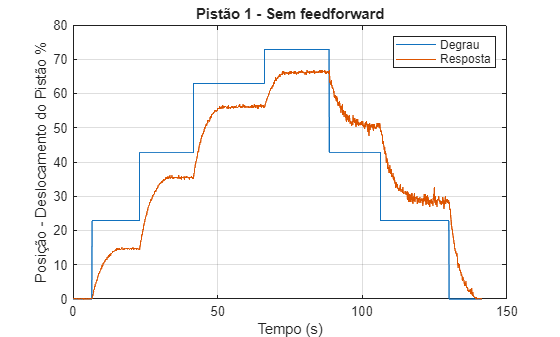

figure(1)
plot(tempo1, degrau1), grid on; hold on;
plot(tempo1, resposta1), hold off;
title('Pistão 1 - Sem feedforward');
xlabel('Tempo (s)');
ylabel('Posição - Deslocamento do Pistão %');
legend('Degrau', 'Resposta');

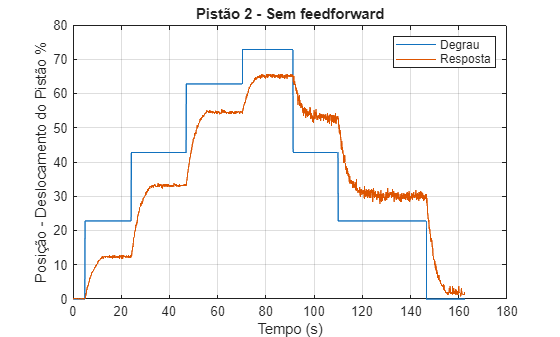


figure(2)
plot(tempo2, degrau2), grid on; hold on;
plot(tempo2, resposta2), hold off;
title('Pistão 2 - Sem feedforward');
xlabel('Tempo (s)');
ylabel('Posição - Deslocamento do Pistão %');
legend('Degrau', 'Resposta');

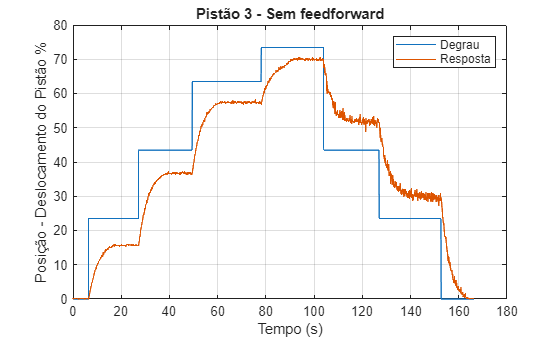


figure(3)
plot(tempo3, degrau3), grid on; hold on;
plot(tempo3, resposta3), hold off;
title('Pistão 3 - Sem feedforward');
xlabel('Tempo (s)');
ylabel('Posição - Deslocamento do Pistão %');
legend('Degrau', 'Resposta');

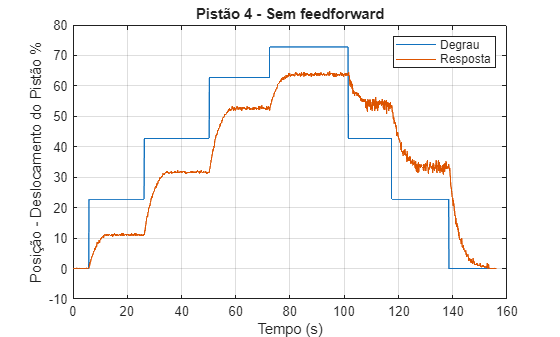


figure(4)
plot(tempo4, degrau4), grid on; hold on;
plot(tempo4, resposta4), hold off;
title('Pistão 4 - Sem feedforward');
xlabel('Tempo (s)');
ylabel('Posição - Deslocamento do Pistão %');
legend('Degrau', 'Resposta');

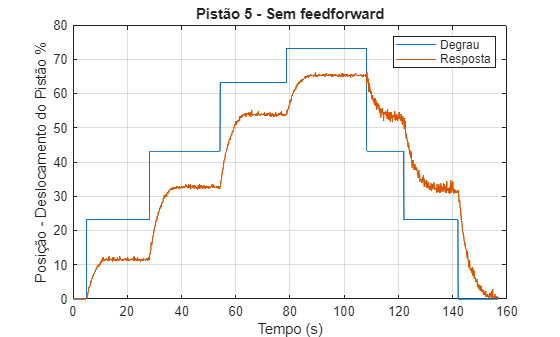


figure(5)
plot(tempo5, degrau5), grid on; hold on;
plot(tempo5, resposta5), hold off;
title('Pistão 5 - Sem feedforward');
xlabel('Tempo (s)');
ylabel('Posição - Deslocamento do Pistão %');
legend('Degrau', 'Resposta');

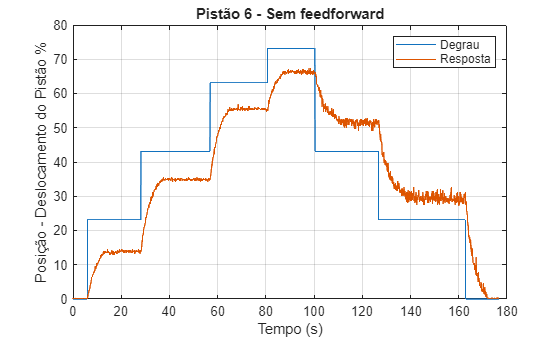


figure(6)
plot(tempo6, degrau6), grid on; hold on;
plot(tempo6, resposta6), hold off;
title('Pistão 6 - Sem feedforward');
xlabel('Tempo (s)');
ylabel('Posição - Deslocamento do Pistão %');
legend('Degrau', 'Resposta');

% Gerando variáveis com o feedforward

tempoff1 = 0;
degrauff1 = 0;
respostaff1 = 0;
tempoff2 = 0;
degrauff2 = 0;
respostaff2 = 0;
tempoff3 = 0;
degrauff3 = 0;
respostaff3 = 0;
tempoff4 = 0;
degrauff4 = 0;
respostaff4 = 0;
tempoff5 = 0;
degrauff5 = 0;
respostaff5 = 0;
tempoff6 = 0;
degrauff6 = 0;
respostaff6 = 0;

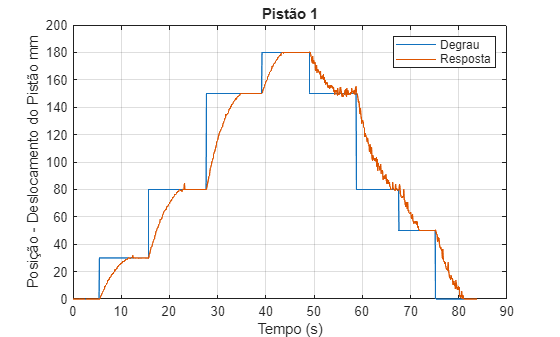

figure(1)
plot(tempoff1, degrauff1), grid on; hold on;
plot(tempoff1, respostaff1), hold off;
title('Pistão 1');
xlabel('Tempo (s)');
ylabel('Posição - Deslocamento do Pistão mm');
legend('Degrau', 'Resposta');

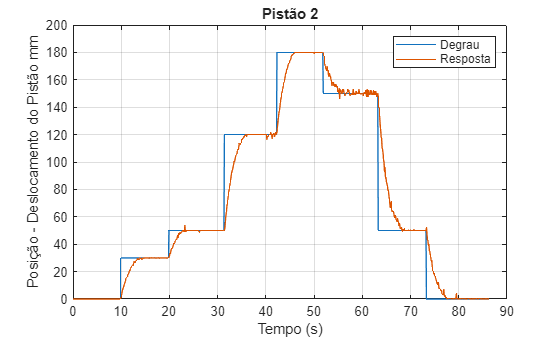


figure(2)
plot(tempoff2, degrauff2), grid on; hold on;
plot(tempoff2, respostaff2), hold off;
title('Pistão 2');
xlabel('Tempo (s)');
ylabel('Posição - Deslocamento do Pistão mm');
legend('Degrau', 'Resposta');

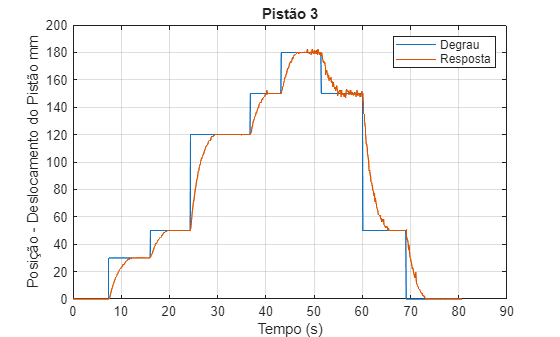


figure(3)
plot(tempoff3, degrauff3), grid on; hold on;
plot(tempoff3, respostaff3), hold off;
title('Pistão 3');
xlabel('Tempo (s)');
ylabel('Posição - Deslocamento do Pistão mm');
legend('Degrau', 'Resposta');

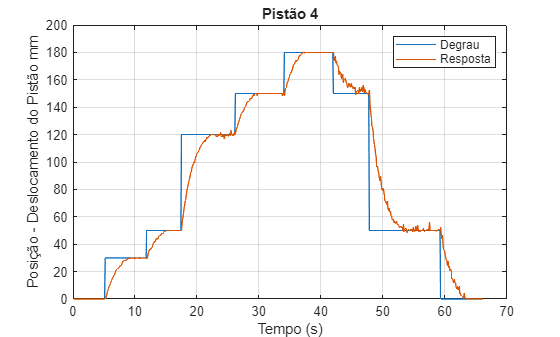


figure(4)
plot(tempoff4, degrauff4), grid on; hold on;
plot(tempoff4, respostaff4), hold off;
title('Pistão 4');
xlabel('Tempo (s)');
ylabel('Posição - Deslocamento do Pistão mm');
legend('Degrau', 'Resposta');

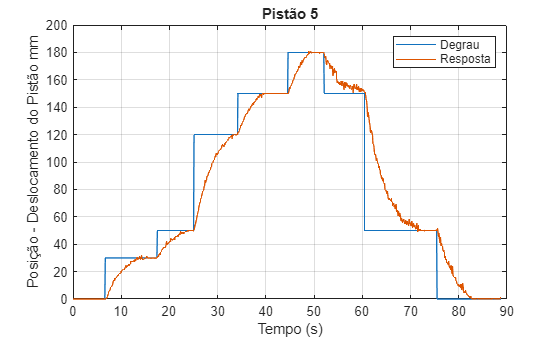


figure(5)
plot(tempoff5, degrauff5), grid on; hold on;
plot(tempoff5, respostaff5), hold off;
title('Pistão 5');
xlabel('Tempo (s)');
ylabel('Posição - Deslocamento do Pistão mm');
legend('Degrau', 'Resposta');

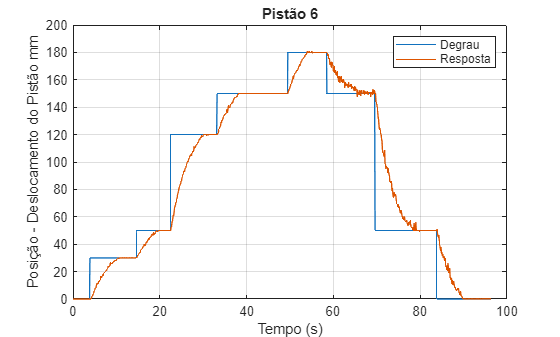


figure(6)
plot(tempoff6, degrauff6), grid on; hold on;
plot(tempoff6, respostaff6), hold off;
title('Pistão 6');
xlabel('Tempo (s)');
ylabel('Posição - Deslocamento do Pistão mm');
legend('Degrau', 'Resposta');

% ===== Malha aberta Pistão 1 =====

% tfpistao1 — função de transferência em malha fechada com Kp=1

T1 = tf(tfpistao1.Numerator, tfpistao1.Denominator);

% Como Kp = 1 e H(s) = 1 (realimentação unitária), G(s) = T / (1 - T)
G1 = minreal( T1 / (1 - T1) );

disp('Função de transferência do Pistão 1 - G(s) em malha aberta:');

Função de transferência do Pistão 1 - G(s) em malha aberta:


G1


G1 =
 
           1.425
  ------------------------
  s^2 + 3.146 s - 0.008129
 
Continuous-time transfer function.



% ===== Malha aberta Pistão 2 =====
T2 = tf(tfpistao2.Numerator, tfpistao2.Denominator);
G2 = minreal( T2 / (1 - T2) );
disp('Função de transferência do Pistão 2 - G(s) em malha aberta:');

Função de transferência do Pistão 2 - G(s) em malha aberta:


G2


G2 =
 
          11.52
  ----------------------
  s^2 + 14.85 s - 0.0444
 
Continuous-time transfer function.



% ===== Malha aberta Pistão 3 =====
T3 = tf(tfpistao3.Numerator, tfpistao3.Denominator);
G3 = minreal( T3 / (1 - T3) );
disp('Função de transferência do Pistão 3 - G(s) em malha aberta:');

Função de transferência do Pistão 3 - G(s) em malha aberta:


G3


G3 =
 
           13.36
  -----------------------
  s^2 + 16.93 s - 0.05487
 
Continuous-time transfer function.



% ===== Malha aberta Pistão 4 =====
T4 = tf(tfpistao4.Numerator, tfpistao4.Denominator);
G4 = minreal( T4 / (1 - T4) );
disp('Função de transferência do Pistão 4 - G(s) em malha aberta:');

Função de transferência do Pistão 4 - G(s) em malha aberta:


G4


G4 =
 
          47.21
  ---------------------
  s^2 + 48.5 s - 0.3616
 
Continuous-time transfer function.



% ===== Malha aberta Pistão 5 =====
T5 = tf(tfpistao5.Numerator, tfpistao5.Denominator);
G5 = minreal( T5 / (1 - T5) );
disp('Função de transferência do Pistão 5 - G(s) em malha aberta:');

Função de transferência do Pistão 5 - G(s) em malha aberta:


G5


G5 =
 
           2.674
  -----------------------
  s^2 + 7.244 s - 0.04952
 
Continuous-time transfer function.



% ===== Malha aberta Pistão 6 =====
T6 = tf(tfpistao6.Numerator, tfpistao6.Denominator);
G6 = minreal( T6 / (1 - T6) );
disp('Função de transferência do Pistão 6 - G(s) em malha aberta:');

Função de transferência do Pistão 6 - G(s) em malha aberta:


G6


G6 =
 
           1.311
  -----------------------
  s^2 + 3.627 s - 0.01289
 
Continuous-time transfer function.


validarConversao(tfpistao1, 'Pistão 1');
validarConversao(tfpistao2, 'Pistão 2');
validarConversao(tfpistao3, 'Pistão 3');
validarConversao(tfpistao4, 'Pistão 4');
validarConversao(tfpistao5, 'Pistão 5');
validarConversao(tfpistao6, 'Pistão 6');

function validarConversao(T, pistaoLabel)
% VALIDARCONVERSAO - Verifica se a conversão de malha fechada para aberta está correta.
% Entradas:
%   T - função de transferência em malha fechada (objeto tf)
%   pistaoLabel - nome do pistão (ex: 'Pistão 1')

    % Certifique-se de que T está como tf
    T = tf(T.Numerator, T.Denominator);

    % Recupera G(s) em malha aberta
    G = minreal( T / (1 - T) );

    % Reconstrói T(s)
    T_rec = minreal( feedback(G, 1) );

    % Diferença
    diff = minreal(T - T_rec);

    % Mostrar resultado
    fprintf('\n--- %s ---\n', pistaoLabel);
    [num_diff, den_diff] = tfdata(diff, 'v');
    disp('Numerador da diferença:');
    disp(num_diff);
    disp('Denominador da diferença:');
    disp(den_diff);

    % Plot comparação
    figure;
    step(T, T_rec);
    title([pistaoLabel ' - T original vs feedback(G)']);
    legend('T original', 'reconstruído de G');
end

% === Controladores PID (ajuste os ganhos manualmente) ===
C1 = pid(1.7829, 0.0249, 0.5175);
C2 = pid(1.0333, 0.0145, 0.0223);
C3 = pid(1.0152, 0.0142, 0.0165);
C4 = pid(0.8221, 0.0143, 0.0000);
C5 = pid(2.1, 0.0813, 0.6177);
C6 = pid(2.2380, 0.0312, 0.5083);

% === Malhas abertas (já extraídas com sucesso antes) ===
% G1, G2, ..., G6 já devem estar no workspace

% === Malhas fechadas ===
T1 = feedback(C1 * G1, 1);
T2 = feedback(C2 * G2, 1);
T3 = feedback(C3 * G3, 1);
T4 = feedback(C4 * G4, 1);
T5 = feedback(C5 * G5, 1);
T6 = feedback(C6 * G6, 1);

% === Gráfico comparativo ===
% === Tempo de simulação ===
t = 0:0.01:80;               % de 0 a 40 segundos, passo de 0.01s
u = 30 * ones(size(t));      % degrau de 30 mm

% === Respostas simuladas com entrada de 30 mm ===
y1 = lsim(T1, u, t);
y2 = lsim(T2, u, t);
y3 = lsim(T3, u, t);
y4 = lsim(T4, u, t);
y5 = lsim(T5, u, t);
y6 = lsim(T6, u, t);

% === Plot ===
figure;
plot(t, y1, t, y2, t, y3, t, y4, t, y5, t, y6, 'LineWidth', 1.5);
title('Resposta ao Degrau de 30 mm - Pistões com Controle PI');
legend('Pistão 1', 'Pistão 2', 'Pistão 3', 'Pistão 4', 'Pistão 5', 'Pistão 6');
ylabel('Posição (mm)');
xlabel('Tempo (s)');
grid on;


% === Controle PID sincronizado sem overshoot ===
% Objetivo: Resposta rápida, sem ultrapassagem e sincronizada entre pistões

% === Parâmetros de projeto ===
velocidade_resposta = 1;  % frequência desejada (rad/s)

% === Projeto dos controladores com pidtune ===
opts = pidtuneOptions('DesignFocus', 'reference-tracking', ...
                      'PhaseMargin', 45);

[C1, ~] = pidtune(G1, 'PID', velocidade_resposta, opts);
[C2, ~] = pidtune(G2, 'PID', velocidade_resposta, opts);
[C3, ~] = pidtune(G3, 'PID', velocidade_resposta, opts);
[C4, ~] = pidtune(G4, 'PID', velocidade_resposta, opts);
[C5, ~] = pidtune(G5, 'PID', velocidade_resposta, opts);
[C6, ~] = pidtune(G6, 'PID', velocidade_resposta, opts);

% === Mostrar os ganhos PID no console ===
controladores = {C1, C2, C3, C4, C5, C6};

fprintf('\n=== Ganhos PID ===\n');


=== Ganhos PID ===


for i = 1:6
    C = controladores{i};

    fprintf('Pistão %d:  Kp = %.4f   Ki = %.4f   Kd = %.4f\n', ...
            i, C.Kp, C.Ki, C.Kd);
end

Pistão 1:  Kp = 2.2853   Ki = 0.0399   Kd = 0.4281
Pistão 2:  Kp = 1.2926   Ki = 0.0226   Kd = 0.0334
Pistão 3:  Kp = 1.2698   Ki = 0.0222   Kd = 0.0259
Pistão 4:  Kp = 1.0277   Ki = 0.0208   Kd = 0.0000
Pistão 5:  Kp = 2.7273   Ki = 0.0476   Kd = 0.2780
Pistão 6:  Kp = 2.7996   Ki = 0.0488   Kd = 0.6882


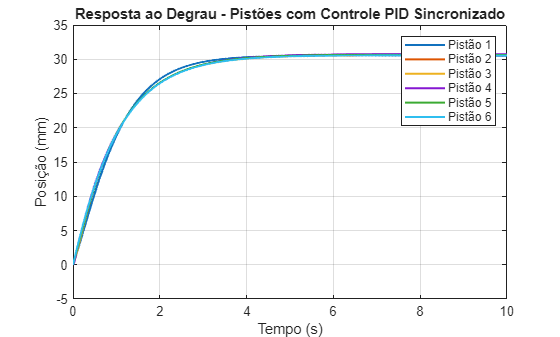


% === Malhas fechadas ===
T1 = feedback(C1 * G1, 1);
T2 = feedback(C2 * G2, 1);
T3 = feedback(C3 * G3, 1);
T4 = feedback(C4 * G4, 1);
T5 = feedback(C5 * G5, 1);
T6 = feedback(C6 * G6, 1);

% === Simulação com degrau de 30 mm ===
t = 0:0.01:10;
u = 30 * ones(size(t));

y1 = lsim(T1, u, t);
y2 = lsim(T2, u, t);
y3 = lsim(T3, u, t);
y4 = lsim(T4, u, t);
y5 = lsim(T5, u, t);
y6 = lsim(T6, u, t);

% === Gráfico comparativo ===
figure;
plot(t, y1, t, y2, t, y3, t, y4, t, y5, t, y6, 'LineWidth', 1.5);
title('Resposta ao Degrau - Pistões com Controle PID Sincronizado');
legend('Pistão 1', 'Pistão 2', 'Pistão 3', 'Pistão 4', 'Pistão 5', 'Pistão 6');
ylabel('Posição (mm)');
xlabel('Tempo (s)');
grid on;

C1c = pid(C1.Kp, C1.Ki, C1.Kd);  % Kp, Ki, Kd
controlSystemDesigner(C1c * G1);

C2c = pid(C2.Kp, C2.Ki, C2.Kd);  % Kp, Ki, Kd
controlSystemDesigner(C2c * G2);

C3c = pid(C3.Kp, C3.Ki, C3.Kd);  % Kp, Ki, Kd
controlSystemDesigner(C3c * G3);

C4c = pid(C4.Kp, C4.Ki, C4.Kd);  % Kp, Ki, Kd
controlSystemDesigner(C4c * G4);

C5c = pid(C5.Kp, C5.Ki, C5.Kd);  % Kp, Ki, Kd
controlSystemDesigner(C5c * G5);

C6c = pid(C6.Kp, C6.Ki, C6.Kd);  % Kp, Ki, Kd
controlSystemDesigner(C6c * G6);